## Extract Beam Patterns

We first extract mic positions for the day on which the experiment was conducted. 

Add functions and parameters to the path.

addpath('beampattern_preprocessing');

1. Specify batID, date, temperature and humidity

date_data = '20240226'; %gui will show files based on this date
T = 24.4; %in deg C
H = 12; %in humidity
floor_mics = [24,28,1,11];

2. Process and save beam pattern data. 

load('parameters_beam_pattern.mat','data');
data = bp_proc(data,cd,0,1:8*data.track.fs,T,H,date_data,floor_mics);

Loading all data and related info...
Processing: 
       bat_pos: 'batDe_11_20240226_D_bat_pos.mat'
      mic_data: 'batDe_11_20240226_093559_mic_data.mat'
    mic_detect: 'batDe_11_20240226_093559_mic_data_detect.mat'
      mic_info: 'mic_info_20240226_landmark01.mat'
      mic_sens: '20230920_mic_sens.mat'
        mic_bp: '20231005_mic_bp.mat'

     head_aim_prescribed: 0
                   tempC: 24.4000
                   humid: 12
        extract_call_len: 10
      call_portion_front: 0.2000
               tolerance: 8
     tukeywin_proportion: 0.2500
               dura_flag: 0
             axis_orient: [1 2 3]
      zero_bat2mic_angle: 0
          call_short_len: 0.5000
                click_th: 0.1000
               click_bpf: [-2.0195e-04 -6.0910e-04 -8.2726e-04 -5.3848e-04 5.3626e-04 0.0018 0.0022 … ]
                PSD_type: 'pwelch'
            RMS_freq_vec: [30000 35000 40000 45000 50000 55000 60000 65000 70000 75000 80000 85000]
           mic_floor_idx: [24 28 1 11]
   

3. Run beam pattern gui and mark "good call"s and correct any weird channels. 

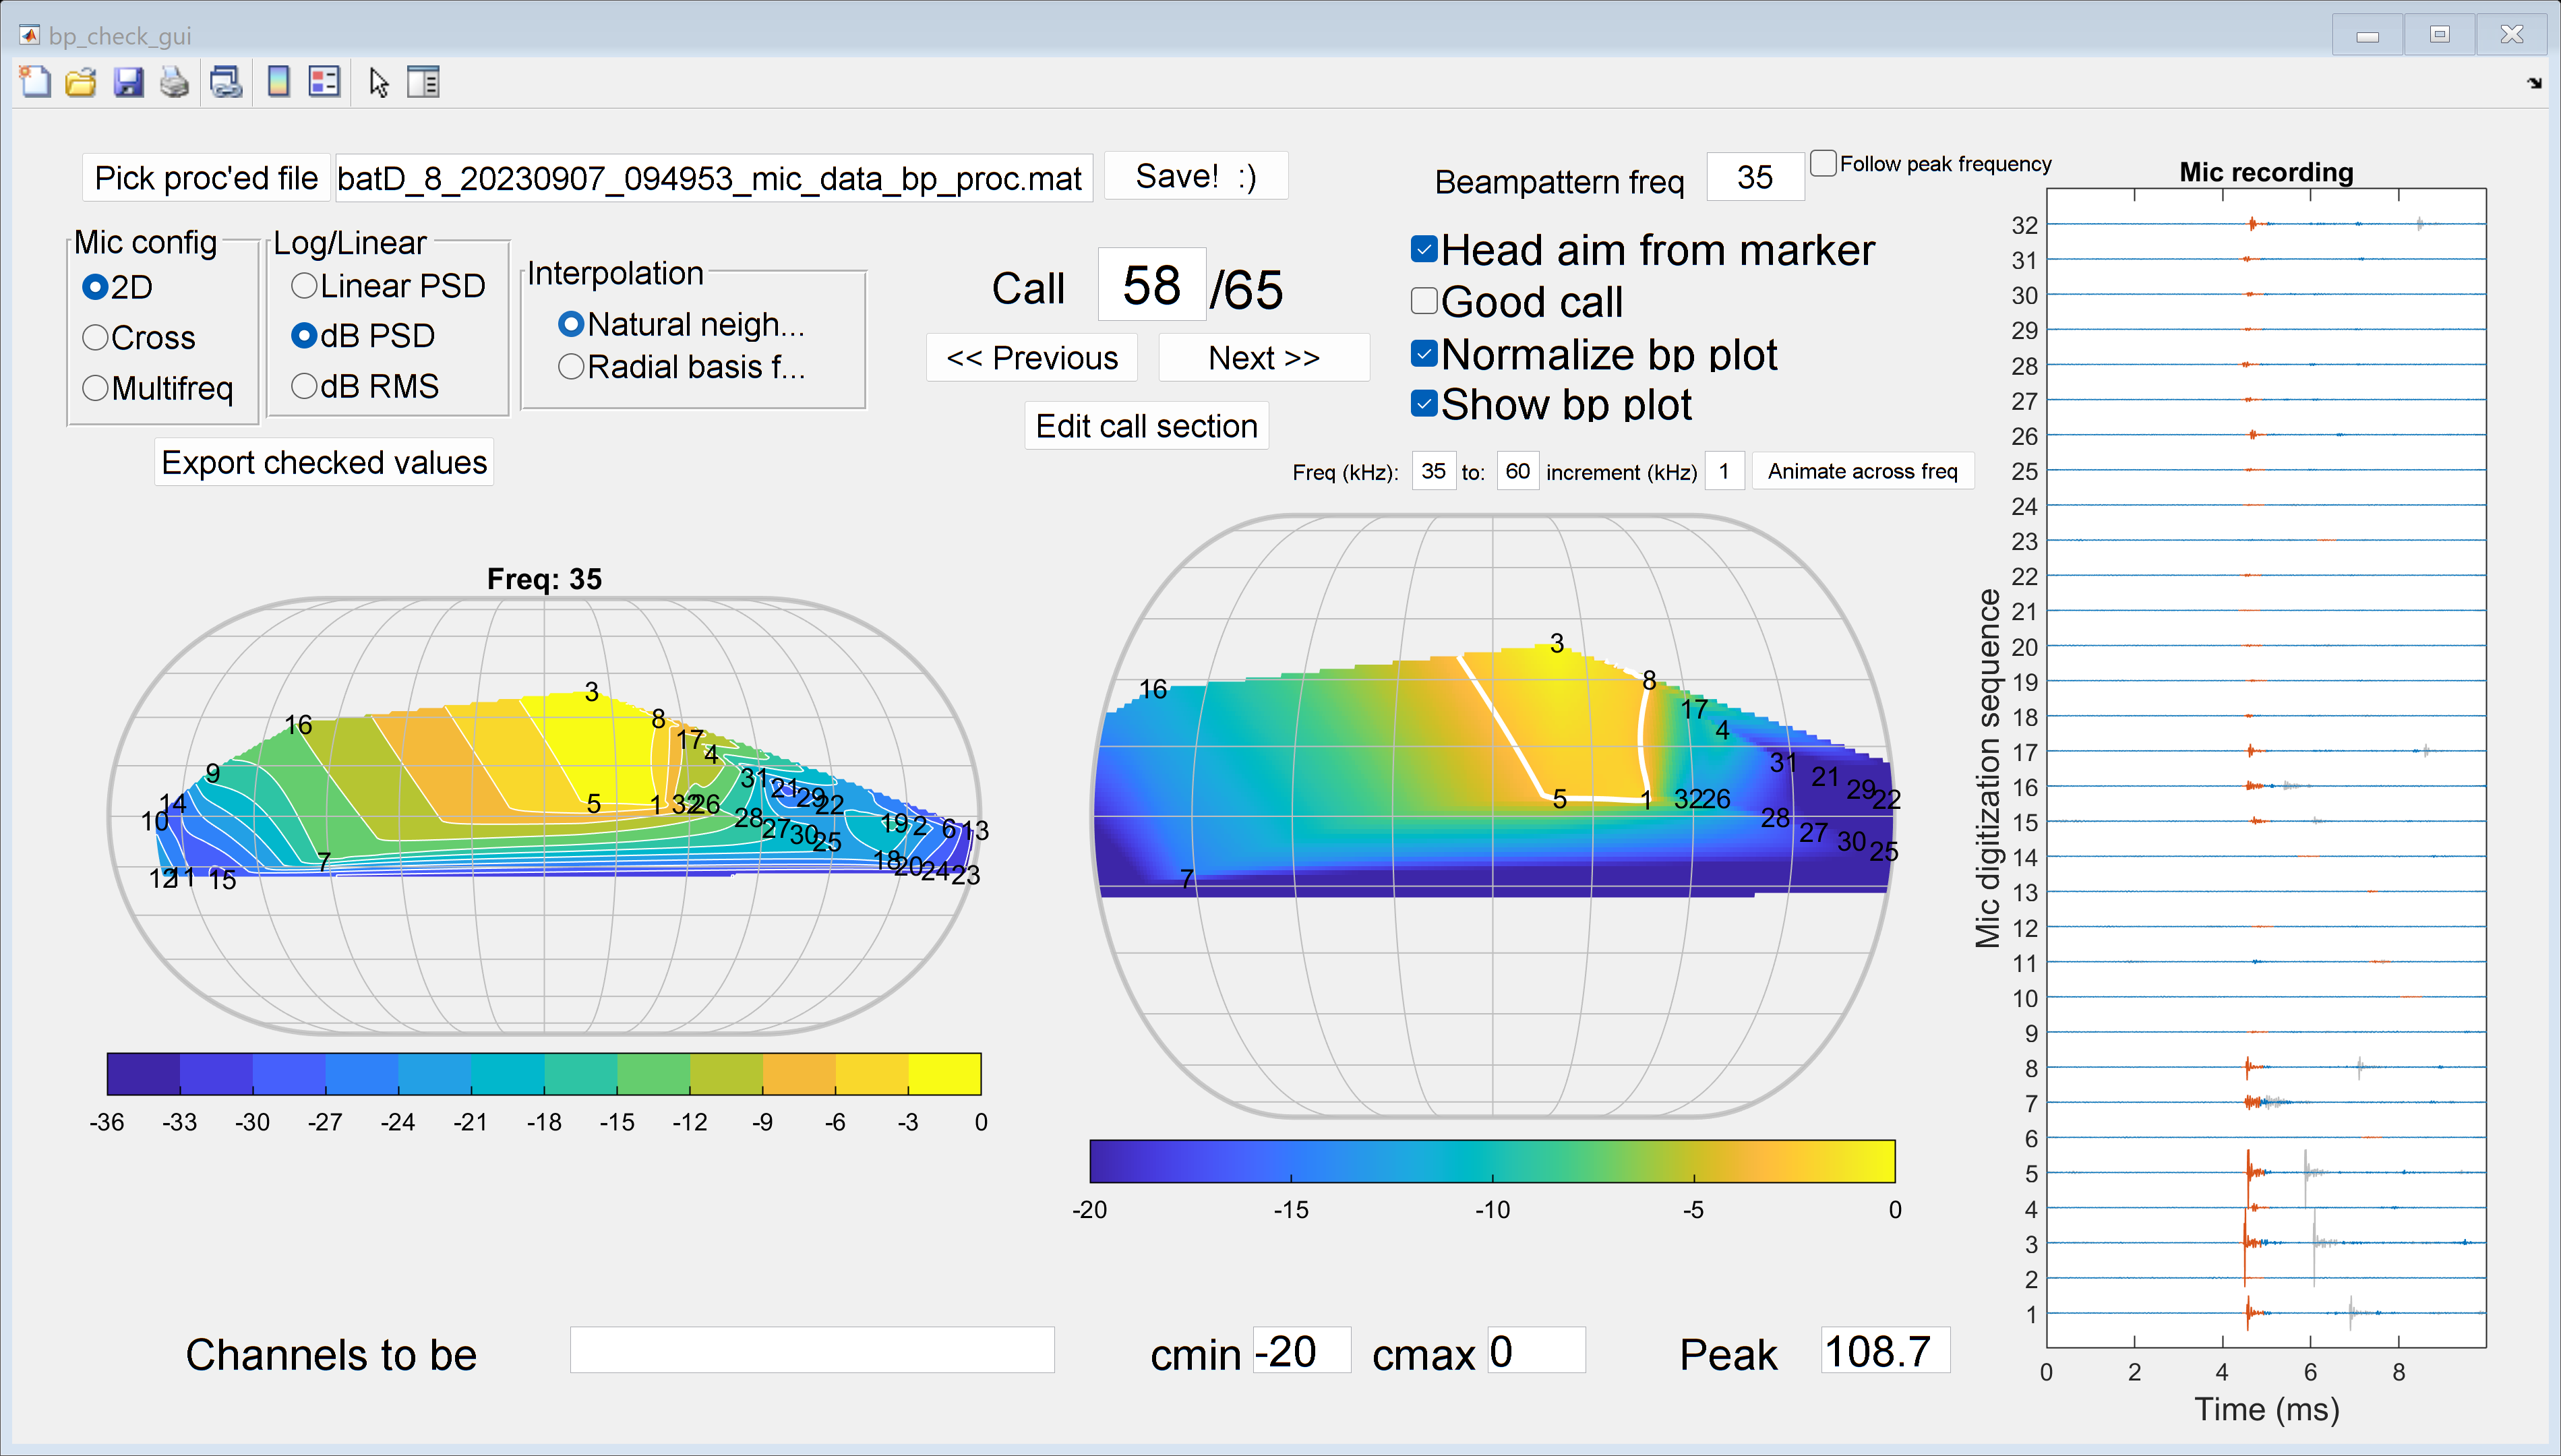

bp_check_gui('date_data',date_data);

freq_desired = 35; % You can change these values as needed
side_view = 0;
save_movie = 1;   

createBeamPatternVideo;

createBeamPatternVideoWithAudio_N;

createBeamPatternVideoWithAudio_V2

createBeamPatternVideo_SpatialMemory_2

createBeamPatternVideo_SpatialMemory